clc; clear all; close all;

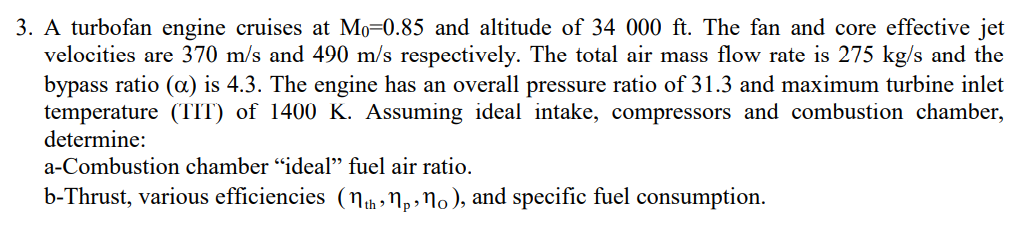

## Data

% Constant Values
Q_R = 2.8*10^7;
P_star_over_p_back=1.893;
gamma_F=1.4;gamma_C=1.4;gamma_T=1.3;gamma_nc=1.3;
e_F =0.86;e_C=0.88;e_T=0;%???   %From Tables 
R = 287; 
% Given
M_0=0.85;
T_0=397.6*0.5555556    % @ h=34000 ft

T_0 = 220.8889

P_0=523.5*47.88026 % @ h=34000 ft

P_0 = 2.5065e+04

V_F_e=370;
V_C_e=490;
m_dot_0=275;
alpha=4.3;
OPR=31.3;
T_4=1400;

Cp_3=1004.5;Cp_4=1088; % not sure

% syms Pb  % at flight condition

## Solution

Tt_0=T_0*(1+(gamma_F-1)/2*M_0^2)

Tt_0 = 252.8074

Pt_0=P_0*(1+(gamma_F-1)/2*M_0^2)^(gamma_F/(gamma_F-1))

Pt_0 = 4.0200e+04

Pb=Pt_0;
% Pt_13=pi_F*Pt_0
% Tt_13=pi_F^(1/e_F-1/gamma_F/e_F)*Tt_0
% assume unchoked nozzle
% V_F_e=((2*gamma_F/(gamma_F-1))*R*Tt_13*(1-(Pb/Pt_13)^(1-1/gamma_F)))^0.5;

syms pi_F
pi_F = vpasolve(V_F_e==((2*gamma_F/(gamma_F-1))*R*(Tt_0*pi_F^(1/e_F-1/gamma_F/e_F))*(1-(Pb/(pi_F*Pt_0))^(1-1/gamma_F)))^0.5,pi_F)

$$pi\_F = 2.2429664678305000431369244436828$$


pi_C=OPR/pi_F

$$pi\_C = 13.95473380851511097069999237274$$


Pt_3=Pt_0*pi_C

$$Pt\_3 = 560983.42829138553744070698730996$$

Tt_3=pi_C^(1/e_C-1/e_C/gamma_C)*Tt_0

$$Tt\_3 = 594.91174826975390761699063275242$$

## fuel air ratio

Tt_4=T_4; % what else !! haha
f=(Cp_4*Tt_4 - Cp_3*Tt_3)/(Q_R - Cp_4*Tt_4)

$$f = 0.034959328501292913033249218538501$$


syms m_dot_F m_dot_C
[m_dot_F,m_dot_C]=vpasolve([alpha==m_dot_F/m_dot_C,m_dot_0==m_dot_F+m_dot_C],m_dot_F,m_dot_C)

$$m\_dot\_F = 223.11320754716981132075471698113$$

$$m\_dot\_C = 51.886792452830188679245283018868$$


m_dot_f=f*m_dot_C

$$m\_dot\_f = 1.8139274222368964309704783203939$$

## Thrust, various efficiencies and specific fuel consumption.

F=m_dot_F*V_F_e + (1+f)*m_dot_C*V_C_e

$$F = 108865.23953123570189268496833926$$

eta_th=(m_dot_F*V_F_e^2+m_dot_C*V_C_e^2)/(2*m_dot_f*Q_R)*100

$$eta\_th = 42.333376870116232259202208112929$$

S=m_dot_f/F*1000

$$S = 0.016662135958617377765211449559462$$